x = ScopeData.signals.values;
y = ScopeData1.signals.values;

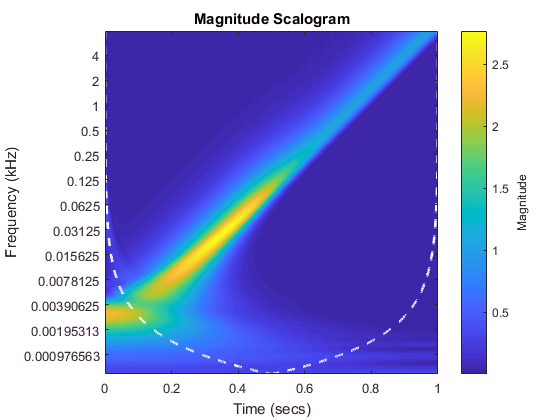

x = ScopeData.signals.values;
y = ScopeData1.signals.values;
%no = 10;
nv = 48;
wvparam = [6 9];

cwt(x_noise,20000,  'VoicesPerOctave', nv,...
    'WaveletParameters',wvparam);

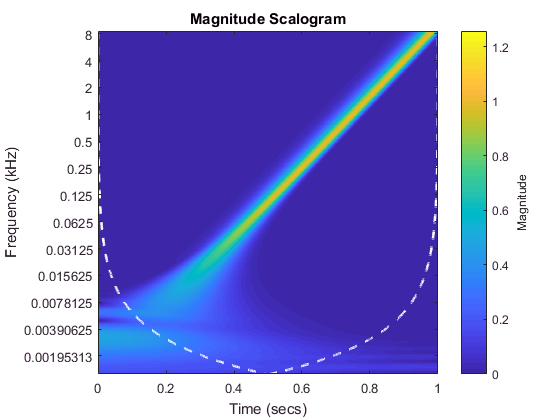

x = ScopeData.signals.values;
y = ScopeData1.signals.values;
nv = 48;
wvparam = [6 30];

cwt(y, 20000,  'VoicesPerOctave', nv,...
    'WaveletParameters',wvparam);

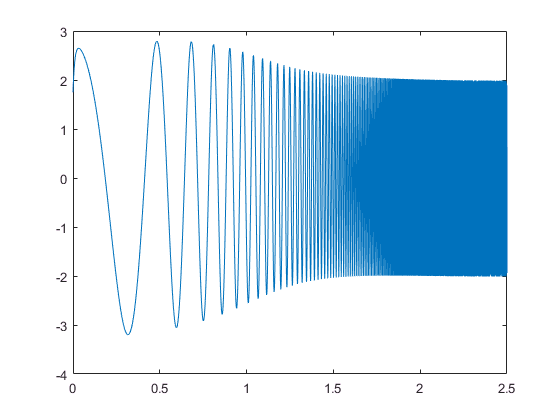

nv = 48;
wvparam = [3 17];
[wt_x, f_x] = cwt(x,10000,  'VoicesPerOctave', nv,...
    'WaveletParameters',wvparam);
yrec = icwt(wt_x,  'VoicesPerOctave', nv,...
    'WaveletParameters',wvparam);
t = ScopeData1.time;
plot(t, yrec)

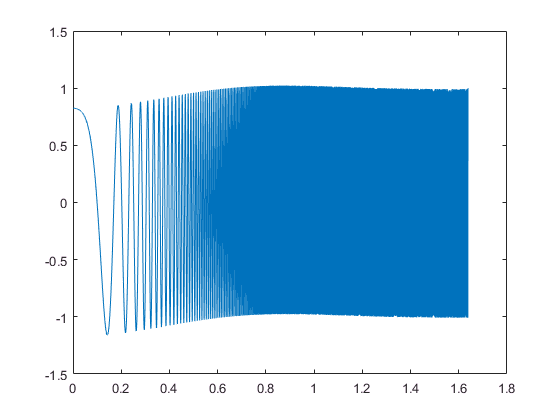

nv = 48;
wvparam = [3 20];

[wt_y, f_y] = cwt(y,10000,  'VoicesPerOctave', nv,...
'WaveletParameters',wvparam);
yrec = icwt(wt_y,  'VoicesPerOctave', nv,...
'WaveletParameters',wvparam);
t = ScopeData1.time;
plot(t, yrec)

nv1 = 10

nv1 = 10

%wcoherence(x,y,10000,'NumOctaves',no, 'VoicesPerOctave', nv1);
%[wcoh,wcs,f]= wcoherence(x,y,10000,'NumOctaves',no, 'VoicesPerOctave', nv1);